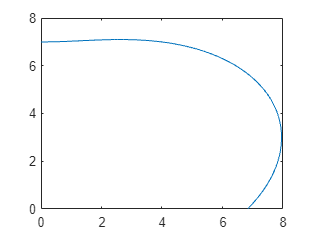

N = 1000;
d = 1000;
n = 1.49;

T = zeros(0,N+1);
T(1) = 0;

R = d*tan(pi/3);

r = zeros(0,N+1);
r(1) = 0;

for i=2:N+1
    T(i) = acos(cos(2*T(i-1))-2/N)/2;
end

for j=2:N+1
    r(j) = R*((j-1)/N)^0.5;
end

Nx = 0;
Ny = 1;

x = zeros(0,N+1);
x(1) = 0;

y = zeros(0,N+1);
y(1) = 7;

for k=2:N+1
    x(k) = ((Nx/Ny)*x(k-1)+y(k-1))/(tan(pi/2-T(k))+(Nx/Ny));
    y(k) = tan(pi/2-T(k))*x(k);
    ox = cos(atan((d-y(k))/(r(k)-x(k))));
    oy = sin(atan((d-y(k))/(r(k)-x(k))));
    ix = sin(T(k));
    iy = cos(T(k));
    Nx = (ox-n*ix)/((1+n^2-2*n*(ox*ix+oy*iy))^0.5);
    Ny = (oy-n*iy)/((1+n^2-2*n*(ox*ix+oy*iy))^0.5);
end

%% 4. 确保实数并移除异常值
if ~isreal(x), x = real(x); end
if ~isreal(y), y = real(y); end
valid = ~(isnan(x) | isnan(y) | isinf(x) | isinf(y));
x = x(valid); y = y(valid);

%% 5. 保存数据（自动选择函数）
M = [x', y'];
if exist('writematrix','file')
    writematrix(M, 'freeformProfile.txt', 'Delimiter', 'tab');
else
    dlmwrite('freeformProfile.txt', M, 'delimiter','\t','precision','%.6f');
end

plot(x,y)